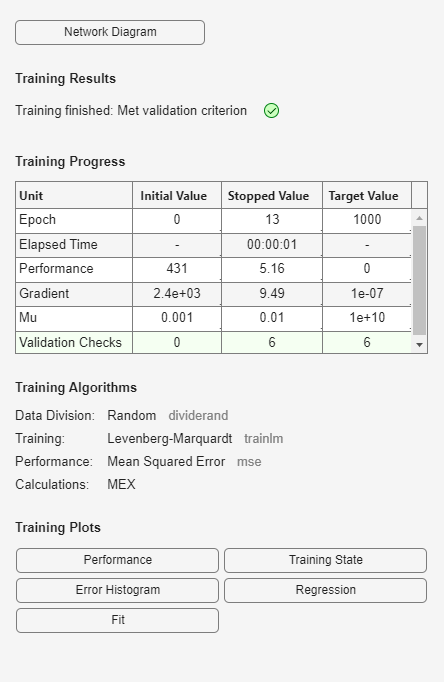

% 问题：假设您有一家健康诊所的数据。您想要设计一个网络，
% 该网络可以基于 13 个解剖学测量值（X）来预测人的体脂率（Y)。
% 您总共有 252 个人的样本，其中包括这 13 项数据和相关的体脂率。
% 采用NFTOOL自动生成代码
% Solve an Input-Output Fitting problem with a Neural Network
% Script generated by NFTOOL
%
clear
load bodyfat_dataset
inputs = bodyfatInputs;
targets = bodyfatTargets;
% Create a Fitting Network
hiddenLayerSize = 10;
net = fitnet(hiddenLayerSize);

% Set up Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
 
% Train the Network
[net,tr] = train(net,inputs,targets);

 
% Test the Network
outputs = net(inputs);
errors = gsubtract(outputs,targets);
performance = perform(net,targets,outputs)

performance = 15.8563

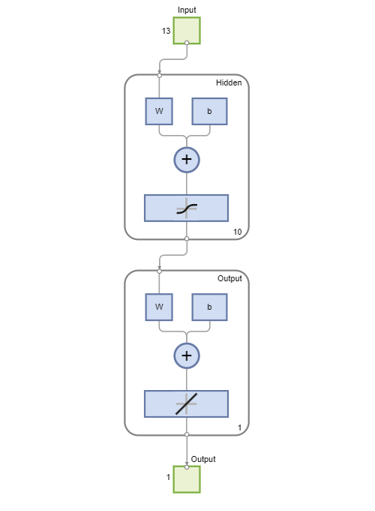

 
% 看网络 View the Network
view(net)

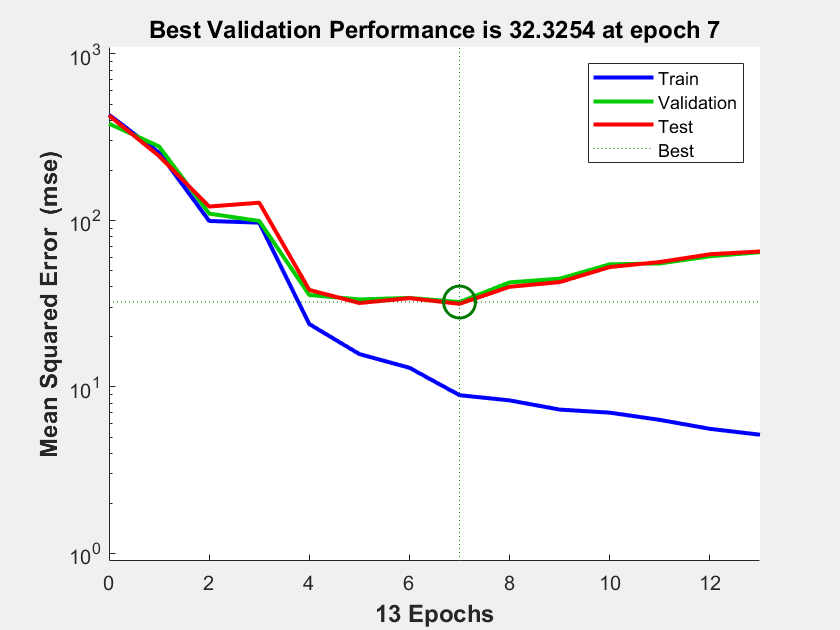

 
% 画图查看网络性能
% Plots
% Uncomment these lines to enable various plots.
figure; plotperform(tr)

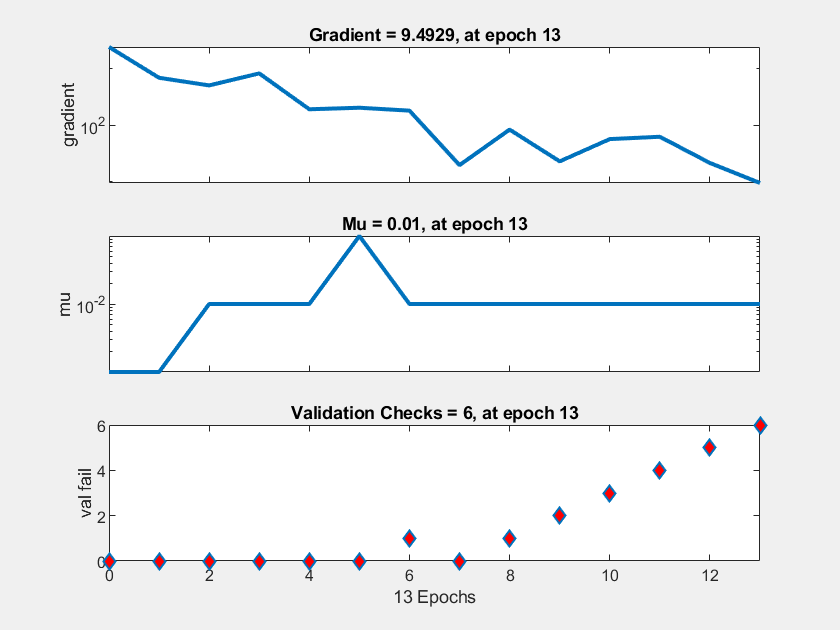

figure; plottrainstate(tr)

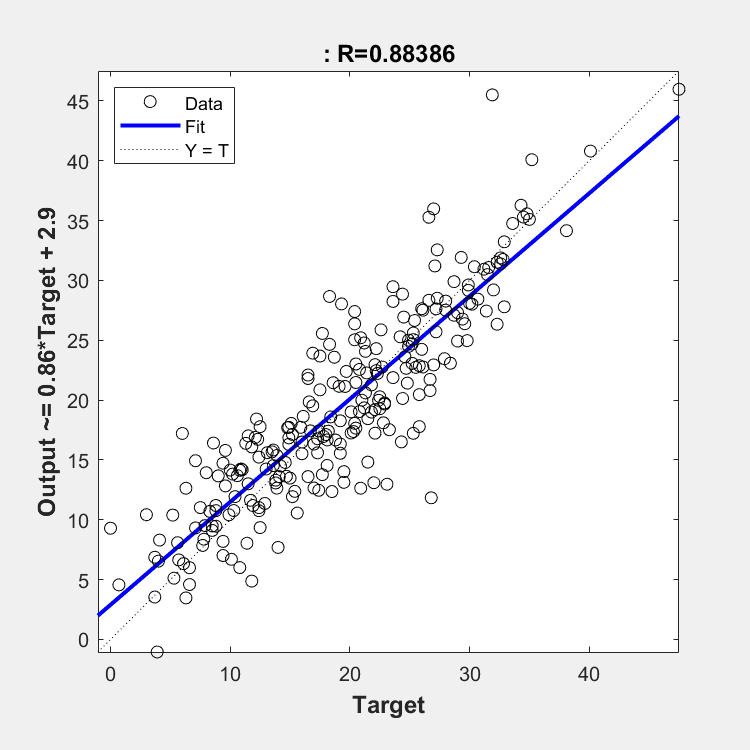

% figure; plotfit(net,inputs,targets)
figure; plotregression(targets,outputs)

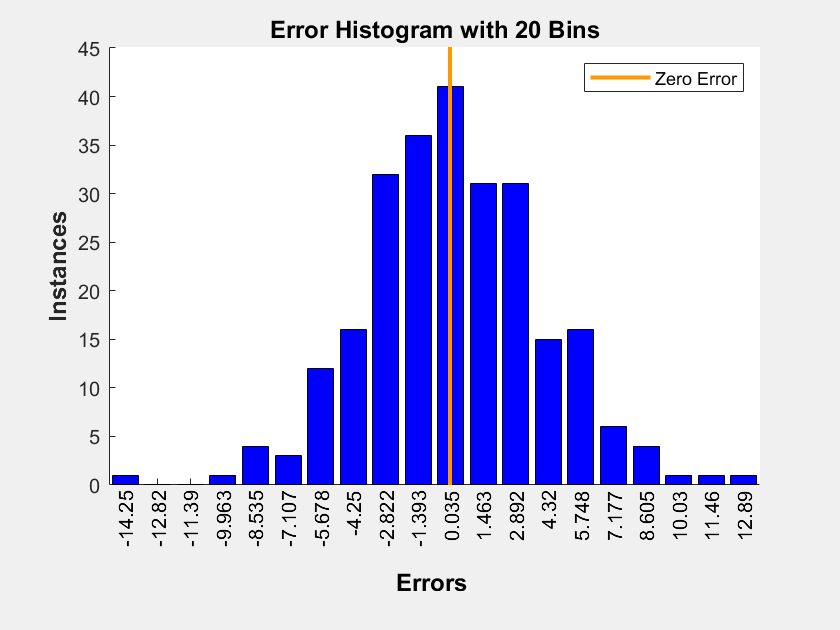

figure; ploterrhist(errors)